# Filtering: Frequency Filtering

In this example, we will learn how to perform the Discrete Fourier Transform (DFT) and its inverse counterpart. Then we will filter some signals in the frequency domain.

% Clear workspace and command window
clear;
clc;

## Fourier transform of signals

### Generate simple signal

It can be shown that any arbitrary discretely sampled signal can be described completely by the sum of a finite number of sine and cosine components whose frequencies are a multiple of the frequency $f=1/n\cdot \Delta x$, where $\Delta x$ is the interval between adjacent x-axis values and n is the total number of points.

We generate a simple sum of two sinusoidal wave signals and add an AWGN noise with a given variance.

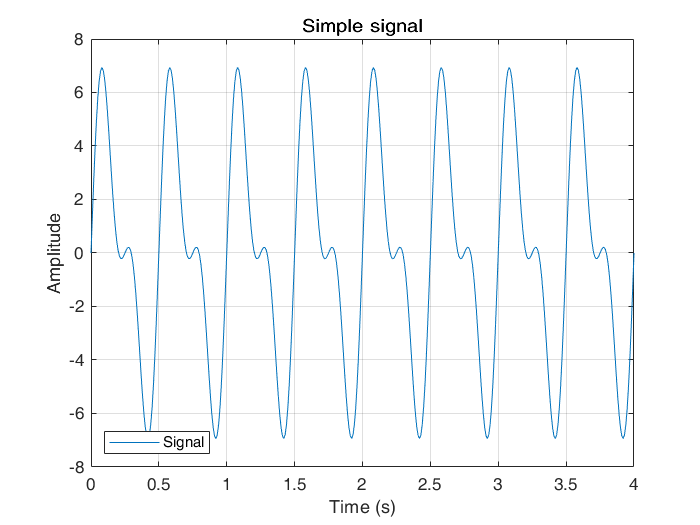

dt = 1/100; % sampling time
et = 4; % end of the interval
t = 0:dt:et; % sampling range
x = 3*sin(4*2*pi*t) + 5*sin(2*2*pi*t); % sample the signal

plot(t,x);
title('Simple signal')
legend({'Signal'},'location','southwest');
xlabel('Time (s)');
ylabel('Amplitude');
axis([0 et -8 8]); % scale axes for viewing
grid on;

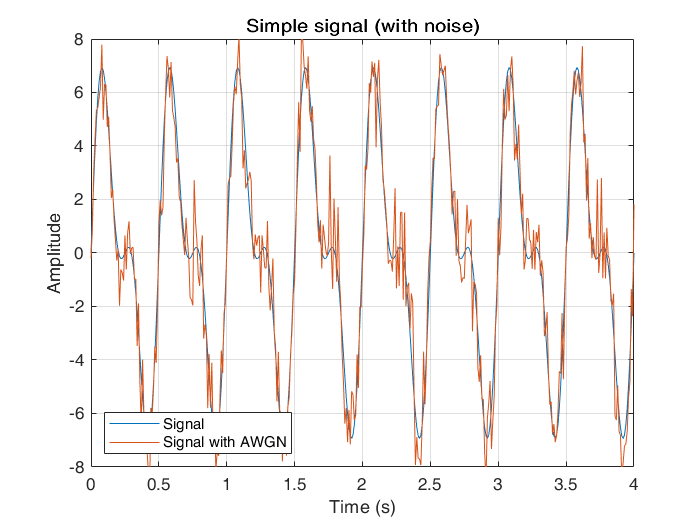



noise_std = 1;
noise = noise_std .* randn(size(t));
x_noise = x + noise; %noisy signal

plot(t,x,t,x_noise);
title('Simple signal (with noise)')
legend({'Signal','Signal with AWGN'},'location','southwest');
xlabel('Time (s)');
ylabel('Amplitude');
axis([0 et -8 8]); % scale axes for viewing
grid on;

### Calculate the Fourier transformation

The [`fft`](https://it.mathworks.com/help/matlab/ref/fft.html) and [`ifft`](https://it.mathworks.com/help/matlab/ref/ifft.html) functions implement the Fourier transform and inverse Fourier transform, respectively. 

Using these functions we plot the amplitude spectrum of the signal.

For real time-domain signals, the FFT produces a symmetric amplitude spectrum. When we will design filters in the next sections, we will think first about the first half and then extend the filter by symmetry.

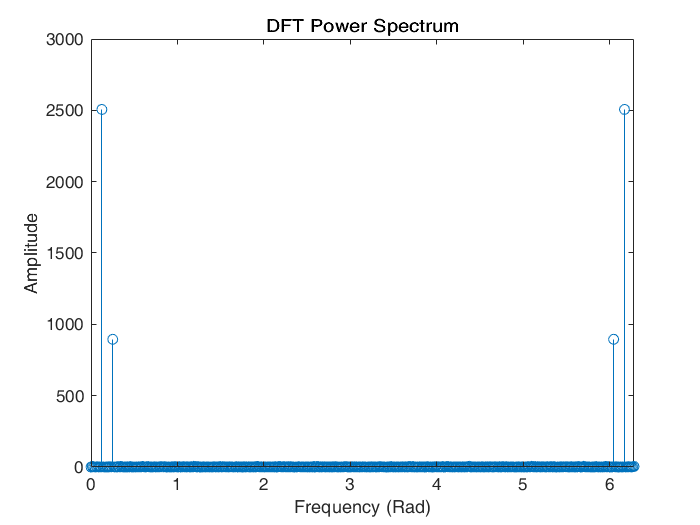

X_noise = fft(x_noise); % Fourier transform of noisy signal
n = size(x_noise,2); 
power_spec = abs(X_noise).^2/n; % power spectrum

freq=linspace(0,2*pi,n); 

stem(freq,power_spec);
title('DFT Power Spectrum')
xlabel('Frequency (Rad)');
ylabel('Amplitude');
xlim([0 2*pi]);

## Low-pass filter in frequency domain

### Create simple signal

To compute the low-pass filter in the frequency domain, we create an ideal filter mask with a cut-off frequency of 0.4. 

Note that [`fliplr`](https://it.mathworks.com/help/matlab/ref/fliplr.html) will flips an array left to right.

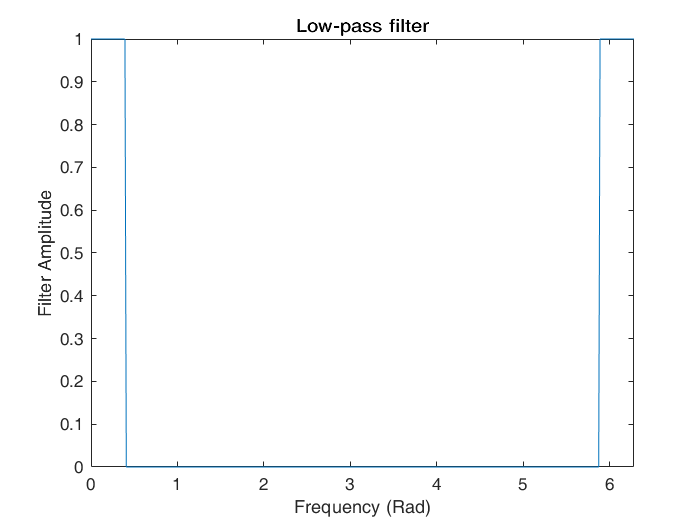

H_lp = freq < 0.4;          % Design the filter for the first half 
H_lp = H_lp + fliplr(H_lp); % Extend the filter by symmetry

plot(freq,H_lp);
xlabel('Frequency (Rad)');
ylabel('Filter Amplitude');
title('Low-pass filter');
xlim([0 2*pi]);

### Apply the frequency filter

We apply the filter in the frequency domain just computing the product between the Fourier transform of the signal and the filter. Then we show the inverse transform to filtered signal in the time domain.

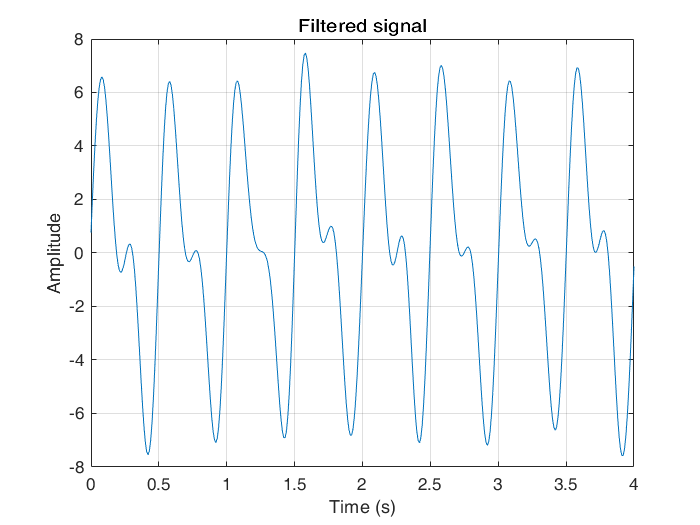

X_lp=X_noise.*H_lp;         % Apply the filter
x_lp=real( ifft( X_lp)  );  % Filtered signal in Time domain

plot(t,x_lp);

xlabel('Time (s)')
ylabel('Amplitude')
title('Filtered signal')
grid on;

## Band-pass filter in frequency domain

### Load the data

The file `quake.mat` contains 200Hz data from the October 17, 1989 [Loma Prieta earthquake in the Santa Cruz Mountains](https://it.mathworks.com/help/matlab/matlab_prog/loma-prieta-earthquake.html). The data are courtesy of Joel Yellin at the Charles F. Richter Seismological Laboratory, University of California, Santa Cruz.

The variables `n`, `e`, `v` refer to the three directional components measured by the instrument, which was aligned parallel to the fault, with its N direction pointing in the direction of Sacramento.

Plot the signal in time and the frequency power spectrum.

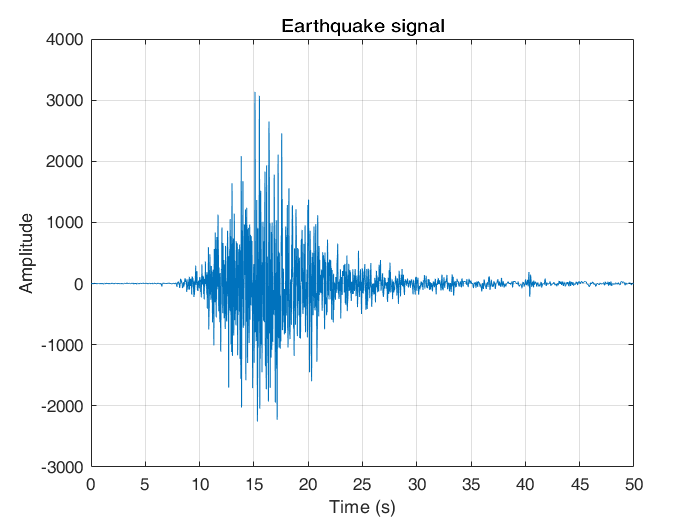

load quake
dt = 1/200; % sampling rate
x = n'; % select the sensor in direction of Sacramento
t = dt .* (1:length(e));

plot(t,x);
title('Earthquake signal')
xlabel('Time (s)');
ylabel('Amplitude');
xlim([0 t(end)]); % scale axes for viewing
grid on;

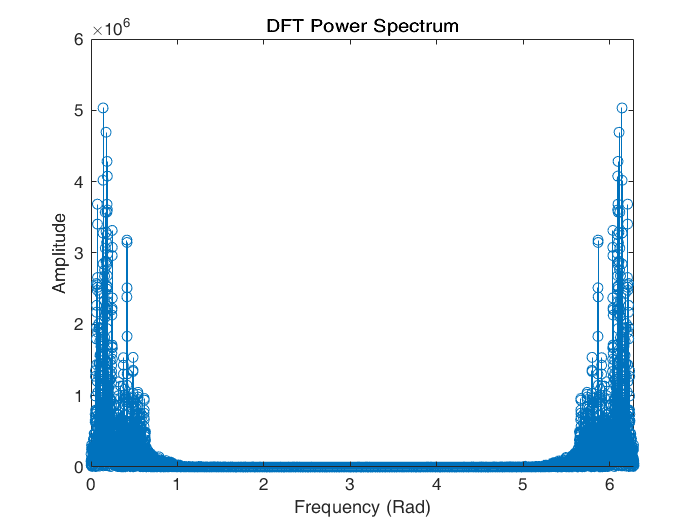


X = fft(x); % compute Fourier transform
n = length(x); 
power_spec = abs(X).^2/n; % power spectrum

freq=linspace(0,2*pi,n); 
stem(freq,power_spec);
title('DFT Power Spectrum')
xlabel('Frequency (Rad)');
ylabel('Amplitude');
xlim([0 2*pi]);

### Apply the frequency filter

We want to clear the high frequency and the very low frequency of the signal by performing an ideal band-pass filter that allows passing frequency between 0.033 to 1.5 radiant.

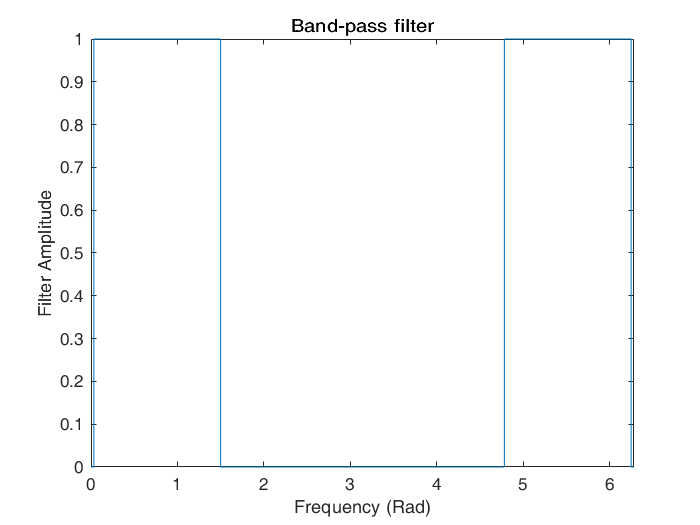

H_bp = (freq > 0.033) .* (freq < 1.5);    % Design the filter for the first half 
H_bp = H_bp + fliplr(H_bp); % Extend the filter by symmetry

plot(freq,H_bp)
xlabel('Frequency (Rad)')
ylabel('Filter Amplitude')
title('Band-pass filter')
xlim([0 2*pi]);

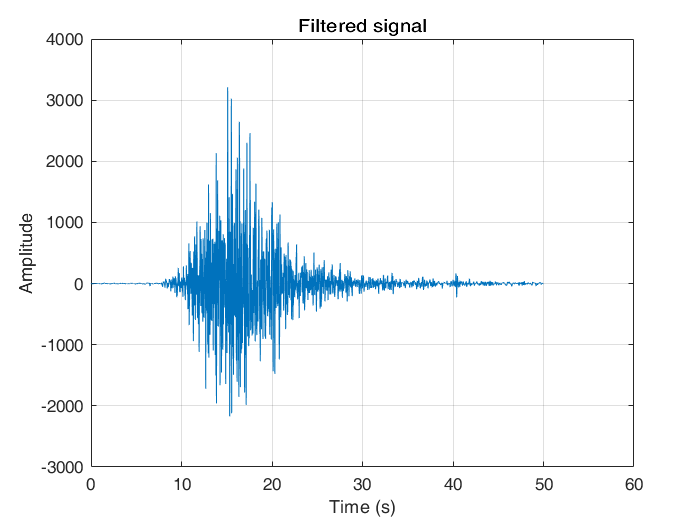


X_bp=X.*H_bp; 
x_bp=real( ifft(X_bp ) ); 

plot(t,x_bp);

xlabel('Time (s)')
ylabel('Amplitude')
title('Filtered signal')
grid on;

## Further Practice

- Try different cut-off frequency of the filter, to see what happen.

- The function [`fir2`](https://it.mathworks.com/help/signal/ref/fir2.html) helps to design frequency-domain filters. Try to rewrite the exercise using it.

- The functions [lowpass](https://it.mathworks.com/help/signal/ref/lowpass.html), [highpass](https://it.mathworks.com/help/signal/ref/highpass.html) and,[bandpass](https://it.mathworks.com/help/signal/ref/bandpass.html) perform directly the filter in the frequency domain. Try to rewrite the exercise using them.

## Further readings

- [lowpass](https://it.mathworks.com/help/signal/ref/lowpass.html), [highpass](https://it.mathworks.com/help/signal/ref/highpass.html) and [bandpass](https://it.mathworks.com/help/signal/ref/bandpass.html)

- [Signal Processing Onramp](https://matlabacademy.mathworks.com/R2020b/portal.html?course=signalprocessing)